clc;clf;
MMS_test(4,500,9,3,60);

到达顾客数:510
服务顾客数:510
损失顾客数:0
平均逗留时间:0.407756
平均等待时间:0.077962
平均服务时间:0.334897
平均队长:3.494831
平均等待队长:0.688779
顾客不能马上得到服务的概率:0.363911


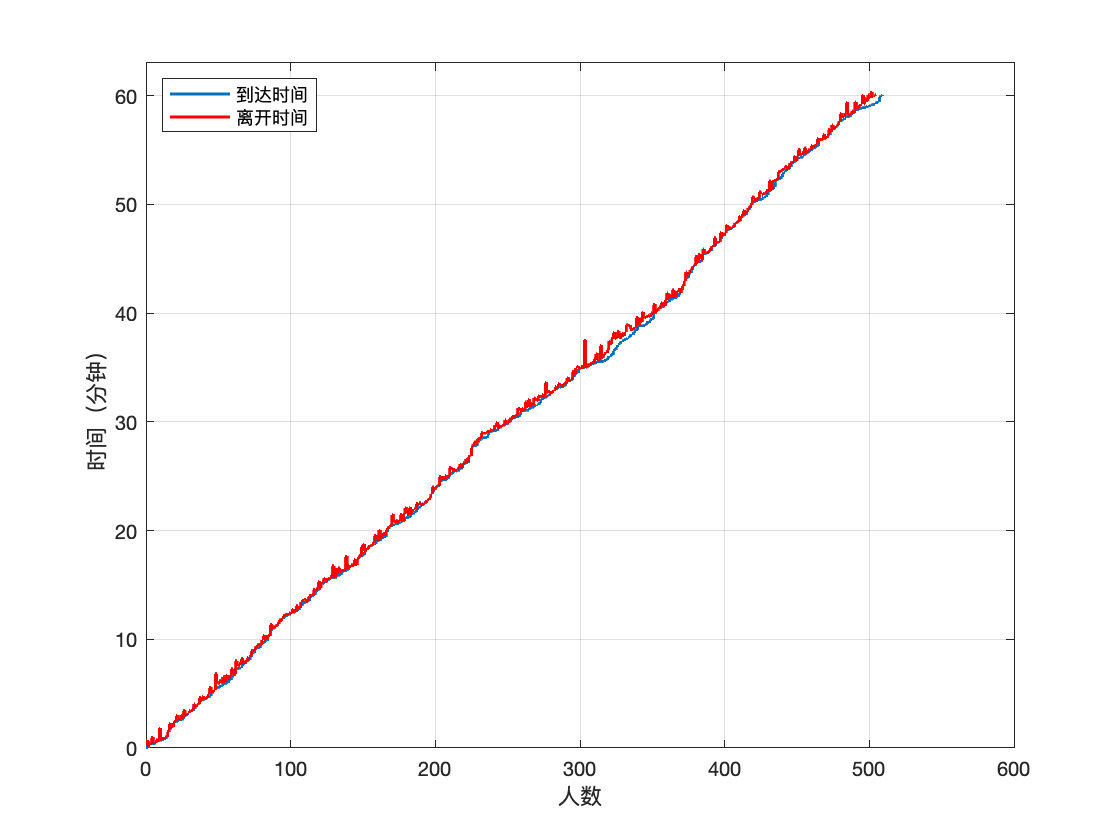


ylim([0 63]);

function out=MMS_test(s,k,lambda,mu,T)
%多服务台
%s——服务台个数
%k——最大顾客等待数
%T——时间终止点
%mu——服务率 
%事件表：
%   arrive_time——顾客到达事件
%   leave_time——顾客离开事件
%mintime——事件表中的最近事件
%current_time——当前时间
%L——队长
%tt——时间序列
%LL——队长序列
%c——顾客到达时间序列
%b——服务开始时间序列
%e——顾客离开时间序列
%a_count——到达顾客数
%b_count——服务顾客数
%e_count——损失顾客数
%初始化
arr_mean = 1/lambda; 
ser_mean = 1/mu; 
arrive_time=exprnd(arr_mean);
leave_time=[];
current_time=0;
L=0;
LL=[L];
tt=[current_time];
c=[];
b=[];
e=[];
a_count=0;
b_count=0;
e_count=0;
arrival = [];
left = [];

%循环
while min([arrive_time,leave_time])<T
    current_time=min([arrive_time,leave_time]);
    tt=[tt,current_time];    %记录时间序列
    if current_time==arrive_time          %顾客到达子过程
        arrive_time=arrive_time+exprnd(arr_mean);  % 刷新顾客到达事件
        arrival=[arrival,arrive_time];
        a_count=a_count+1; %累加到达顾客数
        if  L<s            %有空闲服务台
            L=L+1;        %更新队长
            b_count=b_count+1;%累加服务顾客数
            c=[c,current_time];%记录顾客到达时间序列
            b=[b,current_time];%记录服务开始时间序列
            tmp = current_time+exprnd(ser_mean);
            if tmp < arrive_time
                tmp = arrive_time;
            end
            leave_time=[leave_time,tmp];%产生新的顾客离开事件
            left = [left,tmp];
            leave_time=sort(leave_time);%离开事件表排序
        elseif L<s+k             %有空闲等待位
            L=L+1;        %更新队长
            b_count=b_count+1;%累加服务顾客数
            c=[c,current_time];%记录顾客到达时间序列
        else               %顾客损失
            e_count=e_count+1;%累加损失顾客数
        end
    else                   %顾客离开子过程
            leave_time(1)=[];%从事件表中抹去顾客离开事件
            e=[e,current_time];%记录顾客离开时间序列
            if L>s    %有顾客等待
                L=L-1;        %更新队长
                b=[b,current_time];%记录服务开始时间序列
                tmp = current_time+exprnd(ser_mean);
                leave_time=[leave_time,tmp];
                left = [left,tmp];
                leave_time=sort(leave_time);%离开事件表排序
            else    %无顾客等待
                L=L-1;        %更新队长
            end
    end
    LL=[LL,L];   %记录队长序列
end
Ws=sum(e-c(1:length(e)))/length(e);
Wq=sum(b-c(1:length(b)))/length(b);
Wb=sum(e-b(1:length(e)))/length(e);
Ls=sum(diff([tt,T]).*LL)/T;
Lq=sum(diff([tt,T]).*max(LL-s,0))/T;
fprintf('到达顾客数:%d\n',a_count)%到达顾客数
fprintf('服务顾客数:%d\n',b_count)%服务顾客数
fprintf('损失顾客数:%d\n',e_count)%损失顾客数
fprintf('平均逗留时间:%f\n',Ws)%平均逗留时间
fprintf('平均等待时间:%f\n',Wq)%平均等待时间
fprintf('平均服务时间:%f\n',Wb)%平均服务时间
fprintf('平均队长:%f\n',Ls)%平均队长
fprintf('平均等待队长:%f\n',Lq)%平均等待队长
if k~=inf
   for i=0:s+k
     p(i+1)=sum((LL==i).*diff([tt,T]))/T;%队长为i的概率
%      fprintf('队长为%d的概率:%f\n',i,p(i+1));
   end
else
   for i=0:3*s
     p(i+1)=sum((LL==i).*diff([tt,T]))/T;%队长为i的概率
%      fprintf('队长为%d的概率:%f\n',i,p(i+1));
   end 
end
fprintf('顾客不能马上得到服务的概率:%f\n',1-sum(p(1:s)))%顾客不能马上得到服务的概率
out=[Ws,Wq,Wb,Ls,Lq,p];left = [left,tmp];
stairs(0:length(arrival)-1,arrival,"LineWidth",1.5);
hold on; 
stairs(0:length(left)-1,left,'-r',"LineWidth",1.5); 
legend('到达时间','离开时间'); 
legend('location','northwest');
xlabel('人数');
ylabel('时间（分钟）');
hold off; 
grid on; 
end